Definizione del **numeratore** e del **denominatore** della **FdT**.

num = [1 1];
den = [1 10];

sys = tf(num,den)


sys =
 
  s + 1
  ------
  s + 10
 
Continuous-time transfer function.
Model Properties


Tracciamento del **diagramma di Bode**.

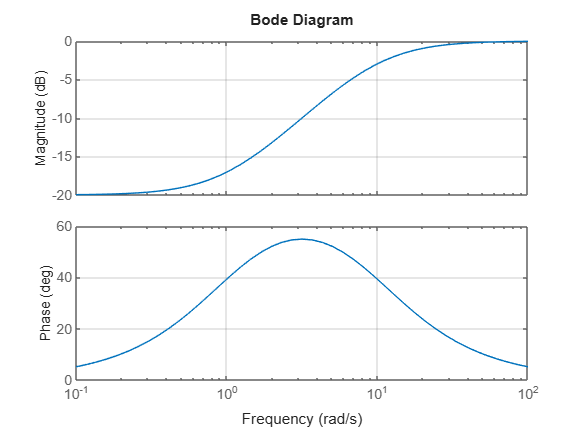

bode(sys,{1/10,100});
grid on

Calcolo di** modulo** e** fase** per w = 1 [rad/s]:

- mag [-] --> per ottenere il valore in db è necessario convertirlo: mag_dB` = 20*log10(mag)`

- phase [gradi]

- wout [rad/s]

[mag,phase,wout] = bode(sys);